data = load("Pomiary\szum_silniki.mat");

tenses = data.out.tens_cal(1:5400, :)

tenses =   -50.6282   47.7605   42.4695  -44.6966
  -50.6524   47.8108   42.6244  -44.6679
  -50.5163   47.7018   42.5221  -44.6679
  -50.4315   47.4520   42.4676  -44.7288
  -50.7232   47.4623   42.1988  -44.8391
  -50.6925   47.5424   42.4963  -44.7315
  -50.6160   47.5564   42.3853  -44.6679
  -50.6337   47.4893   42.4198  -44.6796
  -50.6337   47.5378   42.5164  -44.6885
  -50.7838   47.2311   42.4647  -44.3525
  -50.8528   47.2740   42.3586  -43.8705
  -50.5713   47.5592   42.4025  -43.8705
  -50.5927   47.7372   42.3748  -44.5344
  -50.5927   47.6328   42.2323  -44.5344
  -50.7307   47.3141   42.4064  -44.6079


tenses(:, 1) = tenses(:, 1) - tenses(1, 1);
tenses(:, 2) = tenses(:, 2) - tenses(1, 2);
tenses(:, 3) = tenses(:, 3) - tenses(1, 3);
tenses(:, 4) = tenses(:, 4) - tenses(1, 4);

tenses = tenses * 9.81 / 1000

tenses =          0         0         0         0
   -0.0002    0.0005    0.0015    0.0003
    0.0011   -0.0006    0.0005    0.0003
    0.0019   -0.0030   -0.0000   -0.0003
   -0.0009   -0.0029   -0.0027   -0.0014
   -0.0006   -0.0021    0.0003   -0.0003
    0.0001   -0.0020   -0.0008    0.0003
   -0.0001   -0.0027   -0.0005    0.0002
   -0.0001   -0.0022    0.0005    0.0001
   -0.0015   -0.0052   -0.0000    0.0034
   -0.0022   -0.0048   -0.0011    0.0081
    0.0006   -0.0020   -0.0007    0.0081
    0.0003   -0.0002   -0.0009    0.0016
    0.0003   -0.0013   -0.0023    0.0016
   -0.0010   -0.0044   -0.0006    0.0009


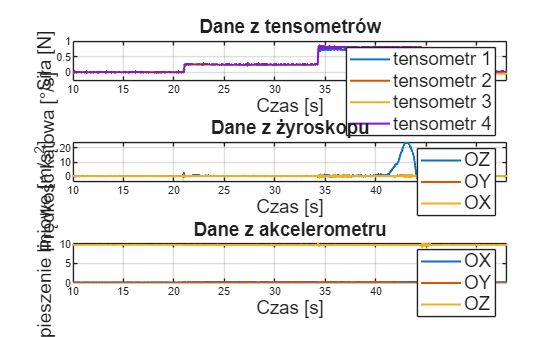

t = 0:0.01:53.99;

figure()
subplot(3, 1, 1);
plot(t, tenses, LineWidth=1.5);
xlim([0, 54])
ylabel("Siła [N]", 'FontSize', 14)
xlabel("Czas [s]", 'FontSize', 14)
title("Dane z tensometrów", 'FontSize', 14)
legend("tensometr 1", "tensometr 2", "tensometr 3", "tensometr 4", 'FontSize', 14)
grid on
xlim([10 53])

subplot(3, 1, 2);
plot(t, data.out.gyro(1:5400, :), LineWidth=1.5);
xlim([0, 54])
xlabel("Czas [s]", 'FontSize', 14)
ylabel("Prędkość kątowa [°/s]", 'FontSize', 14)
title("Dane z żyroskopu", 'FontSize', 14)
legend("OZ", "OY", "OX", 'FontSize', 14)
grid on
xlim([10 53])

subplot(3, 1, 3);
plot(t, data.out.acc(1:5400, :), LineWidth=1.5);
xlim([0, 54])
xlabel("Czas [s]", 'FontSize', 14)
ylabel("Przyspieszenie liniowe [m/s^2]", 'FontSize', 14)
title("Dane z akcelerometru", 'FontSize', 14)
legend("OX", "OY", "OZ", 'FontSize', 14)
grid on
xlim([10 53])

t1 = data.out.tens_cal(1:5400, 1) - data.out.tens_cal(1,1);
t1 = t1 * 9.81 / 1000;
t = 0:0.01:53.99;

lines = zeros(5, 5400);
lines(5,:) = t1;
vec = [1,3,5,8];
cnt = 1;
for i=vec
    
    fs = 85;        % częstotliwość próbkowania [Hz]
    fc = i;         % częstotliwość odcięcia filtru [Hz]
    
    [b, a] = butter(2, fc/(fs/2), 'low');
    
    t1_f_4 = filter(b, a, t1);
    
    lines(cnt, :) = t1_f_4
    cnt = cnt + 1;

end

lines =          0   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002   -0.0003   -0.0003   -0.0004   -0.0005   -0.0005   -0.0006   -0.0006   -0.0007   -0.0007   -0.0007   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

lines =          0   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002   -0.0003   -0.0003   -0.0004   -0.0005   -0.0005   -0.0006   -0.0006   -0.0007   -0.0007   -0.0007   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007
         0   -0.0000    0.0000    0.0000    0.0001    0.0002    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0004   -0.0006   -0.0008   -0.0009   -0.0010   -0.0011   -0.0012   -0.0013   -0.0014   -0.0015   -0.0016   -0.0017   -0.0017   -0.0016   -0.0015   -0.0013   -0.0012   -0.0010   -0.0008   -0.0006   -0.0005   -0.0004   -0.0003   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0003   -0.0004 

lines =          0   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002   -0.0003   -0.0003   -0.0004   -0.0005   -0.0005   -0.0006   -0.0006   -0.0007   -0.0007   -0.0007   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007
         0   -0.0000    0.0000    0.0000    0.0001    0.0002    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0004   -0.0006   -0.0008   -0.0009   -0.0010   -0.0011   -0.0012   -0.0013   -0.0014   -0.0015   -0.0016   -0.0017   -0.0017   -0.0016   -0.0015   -0.0013   -0.0012   -0.0010   -0.0008   -0.0006   -0.0005   -0.0004   -0.0003   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0003   -0.0004 

lines =          0   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002   -0.0003   -0.0003   -0.0004   -0.0005   -0.0005   -0.0006   -0.0006   -0.0007   -0.0007   -0.0007   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007
         0   -0.0000    0.0000    0.0000    0.0001    0.0002    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0004   -0.0006   -0.0008   -0.0009   -0.0010   -0.0011   -0.0012   -0.0013   -0.0014   -0.0015   -0.0016   -0.0017   -0.0017   -0.0016   -0.0015   -0.0013   -0.0012   -0.0010   -0.0008   -0.0006   -0.0005   -0.0004   -0.0003   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0003   -0.0004 

figure()
plt = plot(t, wrev(lines), LineWidth=1.5)

plt =   5×1 Line array:

  Line
  Line
  Line
  Line
  Line


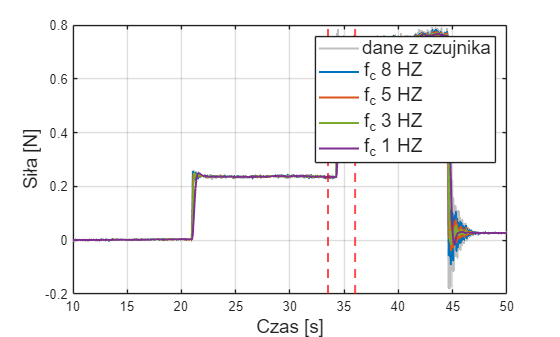

legend("dane z czujnika", ...
    "f_c 8 HZ", ...
    "f_c 5 HZ", ...
    "f_c 3 HZ", ...
    "f_c 1 HZ", 'FontSize', 14)
plt(1).Color = [0.75 0.75 0.75];
plt(2).Color = [0.00 0.45 0.74;];
plt(3).Color = [0.85 0.33 0.10];
plt(4).Color = [0.47 0.67 0.19];
plt(5).Color = [0.49 0.18 0.56 ];
xline([33.5, 36], 'r--', 'LineWidth', 1.5, ...
    'HandleVisibility', 'off');
ylabel("Siła [N]", 'FontSize', 14)
xlabel("Czas [s]", 'FontSize', 14)
grid on 
xlim([10 50])


t_short = 33.5:0.01:36

t_short =    33.5000   33.5100   33.5200   33.5300   33.5400   33.5500   33.5600   33.5700   33.5800   33.5900   33.6000   33.6100   33.6200   33.6300   33.6400   33.6500   33.6600   33.6700   33.6800   33.6900   33.7000   33.7100   33.7200   33.7300   33.7400   33.7500   33.7600   33.7700   33.7800   33.7900   33.8000   33.8100   33.8200   33.8300   33.8400   33.8500   33.8600   33.8700   33.8800   33.8900   33.9000   33.9100   33.9200   33.9300   33.9400   33.9500   33.9600   33.9700   33.9800   33.9900


plt = plot(t_short, wrev(lines(:, 3350:3600)), LineWidth=1.5)

plt =   5×1 Line array:

  Line
  Line
  Line
  Line
  Line


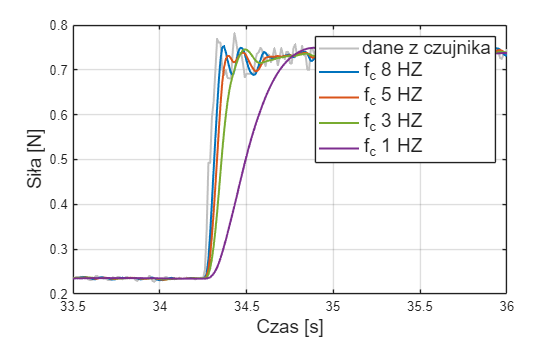

legend("dane z czujnika", ...
    "f_c 8 HZ", ...
    "f_c 5 HZ", ...
    "f_c 3 HZ", ...
    "f_c 1 HZ", 'FontSize', 14)
plt(1).Color = [0.75 0.75 0.75];
plt(2).Color = [0.00 0.45 0.74;];
plt(3).Color = [0.85 0.33 0.10];
plt(4).Color = [0.47 0.67 0.19];
plt(5).Color = [0.49 0.18 0.56 ];
xlim([33.5, 36])
ylabel("Siła [N]", 'FontSize', 14)
xlabel("Czas [s]", 'FontSize', 14)
grid on 

lines = zeros(4, 5400);
lines(4,:) = t1;
vec = [2,4,6];
cnt = 1;
for i=vec
    
    fs = 85;        % częstotliwość próbkowania [Hz]
    fc = 3;         % częstotliwość odcięcia filtru [Hz]
    
    [b, a] = butter(i, fc/(fs/2), 'low');
    
    t1_f_4 = filter(b, a, t1);
        
    lines(cnt, :) = t1_f_4
    cnt = cnt + 1;

end

lines =          0   -0.0000    0.0000    0.0000    0.0001    0.0002    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0004   -0.0006   -0.0008   -0.0009   -0.0010   -0.0011   -0.0012   -0.0013   -0.0014   -0.0015   -0.0016   -0.0017   -0.0017   -0.0016   -0.0015   -0.0013   -0.0012   -0.0010   -0.0008   -0.0006   -0.0005   -0.0004   -0.0003   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0003   -0.0004   -0.0005
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

lines =          0   -0.0000    0.0000    0.0000    0.0001    0.0002    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0004   -0.0006   -0.0008   -0.0009   -0.0010   -0.0011   -0.0012   -0.0013   -0.0014   -0.0015   -0.0016   -0.0017   -0.0017   -0.0016   -0.0015   -0.0013   -0.0012   -0.0010   -0.0008   -0.0006   -0.0005   -0.0004   -0.0003   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0003   -0.0004   -0.0005
         0   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000   -0.0000   -0.0001   -0.0001   -0.0002   -0.0003   -0.0004   -0.0005   -0.0006   -0.0007   -0.0009   -0.0010   -0.0011   -0.0012   -0.0014   -0.0015   -0.0015   -0.0016   -0.0016   -0.0016   -0.0015   -0.0015   -0.0014   -0.0012   -0.0011   -0.0009   -0.0008   -0.0006   -0.0005   -0.0004   -0.0003   -0.0002   -0.0001   -0.0001 

lines =          0   -0.0000    0.0000    0.0000    0.0001    0.0002    0.0002    0.0002    0.0001    0.0001    0.0000   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0004   -0.0006   -0.0008   -0.0009   -0.0010   -0.0011   -0.0012   -0.0013   -0.0014   -0.0015   -0.0016   -0.0017   -0.0017   -0.0016   -0.0015   -0.0013   -0.0012   -0.0010   -0.0008   -0.0006   -0.0005   -0.0004   -0.0003   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0003   -0.0004   -0.0005
         0   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000   -0.0000   -0.0001   -0.0001   -0.0002   -0.0003   -0.0004   -0.0005   -0.0006   -0.0007   -0.0009   -0.0010   -0.0011   -0.0012   -0.0014   -0.0015   -0.0015   -0.0016   -0.0016   -0.0016   -0.0015   -0.0015   -0.0014   -0.0012   -0.0011   -0.0009   -0.0008   -0.0006   -0.0005   -0.0004   -0.0003   -0.0002   -0.0001   -0.0001 

figure()
plt = plot(t, wrev(lines), LineWidth=1.5)

plt =   4×1 Line array:

  Line
  Line
  Line
  Line


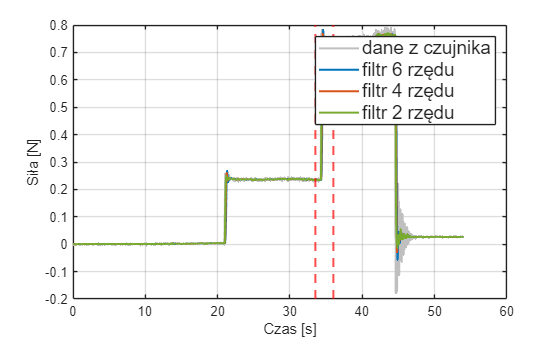

legend("dane z czujnika", ...
    "filtr 6 rzędu", ...
    "filtr 4 rzędu", ...
    "filtr 2 rzędu", 'FontSize', 14)
plt(1).Color = [0.75 0.75 0.75];
plt(2).Color = [0.00 0.45 0.74;];
plt(3).Color = [0.85 0.33 0.10];
plt(4).Color = [0.47 0.67 0.19];
xline([33.5, 36], 'r--', 'LineWidth', 1.5, ...
    'HandleVisibility', 'off');
ylabel("Siła [N]")
xlabel("Czas [s]")
grid on 


t_short = 33.5:0.01:36

t_short =    33.5000   33.5100   33.5200   33.5300   33.5400   33.5500   33.5600   33.5700   33.5800   33.5900   33.6000   33.6100   33.6200   33.6300   33.6400   33.6500   33.6600   33.6700   33.6800   33.6900   33.7000   33.7100   33.7200   33.7300   33.7400   33.7500   33.7600   33.7700   33.7800   33.7900   33.8000   33.8100   33.8200   33.8300   33.8400   33.8500   33.8600   33.8700   33.8800   33.8900   33.9000   33.9100   33.9200   33.9300   33.9400   33.9500   33.9600   33.9700   33.9800   33.9900


plt = plot(t_short, wrev(lines(:, 3350:3600)), LineWidth=1.5)

plt =   4×1 Line array:

  Line
  Line
  Line
  Line


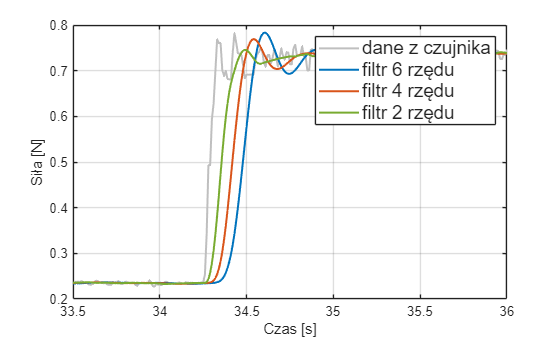

legend("dane z czujnika", ...
    "filtr 6 rzędu", ...
    "filtr 4 rzędu", ...
    "filtr 2 rzędu", 'FontSize', 14)
plt(1).Color = [0.75 0.75 0.75];
plt(2).Color = [0.00 0.45 0.74;];
plt(3).Color = [0.85 0.33 0.10];
plt(4).Color = [0.47 0.67 0.19];
xlim([33.5, 36])
ylabel("Siła [N]")
xlabel("Czas [s]")
grid on 

t = 0:0.01:53.99;

lines_lp = zeros(5, 5400);
lines_lp(5,:) = t1;
vec = [1,3,5,8];
cnt = 1;
for i=vec
    
    fs = 85;        % częstotliwość próbkowania [Hz]
    fc = i;         % częstotliwość odcięcia filtru [Hz]
    
    [b, a] = butter(2, fc/(fs/2), 'low');
    
    t1_f_4 = filter(b, a, t1);
    
    [t1_lp, d] = lowpass(t1, fc/(fs/2), ImpulseResponse="iir");
     n = filtord(d)
    lines_lp(cnt, :) = filter(d, t1)
    cnt = cnt + 1;

    % legend('dane z czujnika', 'butter', )
    % title(i)  

    % figure()
    % plot(t, [t1, t1_f_4, t1_lp], LineWidth=1.5)
    % legend('dane z czujnika', 'lowpass', )
    % title(i)
end

n = 3

lines_lp =          0   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002   -0.0003   -0.0003   -0.0004   -0.0004   -0.0005   -0.0005   -0.0006   -0.0006   -0.0007   -0.0007   -0.0008   -0.0008   -0.0008   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

n = 5

lines_lp =          0   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002   -0.0003   -0.0003   -0.0004   -0.0004   -0.0005   -0.0005   -0.0006   -0.0006   -0.0007   -0.0007   -0.0008   -0.0008   -0.0008   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009
         0   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0004   -0.0005   -0.0006   -0.0008   -0.0009   -0.0010   -0.0011   -0.0013   -0.0014   -0.0014   -0.0015   -0.0016   -0.0016   -0.0016   -0.0015   -0.0015   -0.0014   -0.0013   -0.0011   -0.0010   -0.0008   -0.0007   -0.0005   -0.0004   -0.00

n = 5

lines_lp =          0   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002   -0.0003   -0.0003   -0.0004   -0.0004   -0.0005   -0.0005   -0.0006   -0.0006   -0.0007   -0.0007   -0.0008   -0.0008   -0.0008   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009
         0   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0004   -0.0005   -0.0006   -0.0008   -0.0009   -0.0010   -0.0011   -0.0013   -0.0014   -0.0014   -0.0015   -0.0016   -0.0016   -0.0016   -0.0015   -0.0015   -0.0014   -0.0013   -0.0011   -0.0010   -0.0008   -0.0007   -0.0005   -0.0004   -0.00

n = 6

lines_lp =          0   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002   -0.0003   -0.0003   -0.0004   -0.0004   -0.0005   -0.0005   -0.0006   -0.0006   -0.0007   -0.0007   -0.0008   -0.0008   -0.0008   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009
         0   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0004   -0.0005   -0.0006   -0.0008   -0.0009   -0.0010   -0.0011   -0.0013   -0.0014   -0.0014   -0.0015   -0.0016   -0.0016   -0.0016   -0.0015   -0.0015   -0.0014   -0.0013   -0.0011   -0.0010   -0.0008   -0.0007   -0.0005   -0.0004   -0.00

figure()
plt = plot(t, wrev(lines_lp), LineWidth=1.5)

plt =   5×1 Line array:

  Line
  Line
  Line
  Line
  Line


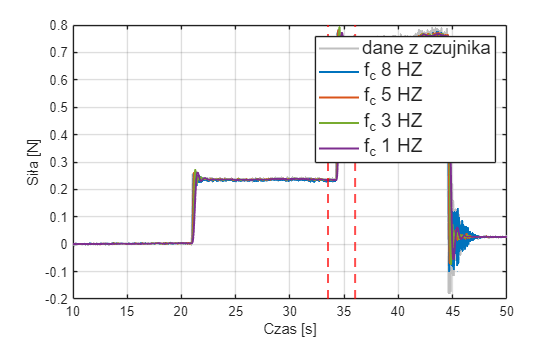

legend("dane z czujnika", ...
    "f_c 8 HZ", ...
    "f_c 5 HZ", ...
    "f_c 3 HZ", ...
    "f_c 1 HZ", 'FontSize', 14)
plt(1).Color = [0.75 0.75 0.75];
plt(2).Color = [0.00 0.45 0.74;];
plt(3).Color = [0.85 0.33 0.10];
plt(4).Color = [0.47 0.67 0.19];
plt(5).Color = [0.49 0.18 0.56 ];
xline([33.5, 36], 'r--', 'LineWidth', 1.5, ...
    'HandleVisibility', 'off');
ylabel("Siła [N]")
xlabel("Czas [s]")
grid on 
xlim([10 50])


t_short = 33.5:0.01:36

t_short =    33.5000   33.5100   33.5200   33.5300   33.5400   33.5500   33.5600   33.5700   33.5800   33.5900   33.6000   33.6100   33.6200   33.6300   33.6400   33.6500   33.6600   33.6700   33.6800   33.6900   33.7000   33.7100   33.7200   33.7300   33.7400   33.7500   33.7600   33.7700   33.7800   33.7900   33.8000   33.8100   33.8200   33.8300   33.8400   33.8500   33.8600   33.8700   33.8800   33.8900   33.9000   33.9100   33.9200   33.9300   33.9400   33.9500   33.9600   33.9700   33.9800   33.9900


plt = plot(t_short, wrev(lines_lp(:, 3350:3600)), LineWidth=1.5)

plt =   5×1 Line array:

  Line
  Line
  Line
  Line
  Line


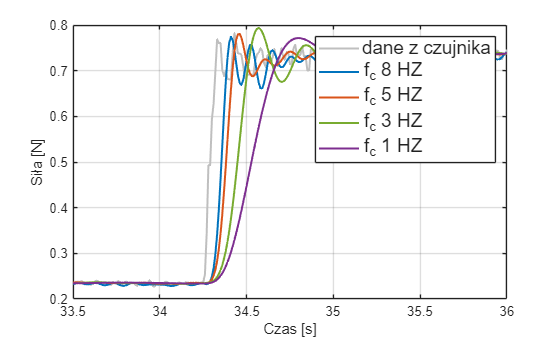

legend("dane z czujnika", ...
    "f_c 8 HZ", ...
    "f_c 5 HZ", ...
    "f_c 3 HZ", ...
    "f_c 1 HZ", 'FontSize', 14)
plt(1).Color = [0.75 0.75 0.75];
plt(2).Color = [0.00 0.45 0.74;];
plt(3).Color = [0.85 0.33 0.10];
plt(4).Color = [0.47 0.67 0.19];
plt(5).Color = [0.49 0.18 0.56 ];
xlim([33.5, 36])
ylabel("Siła [N]")
xlabel("Czas [s]")
grid on 

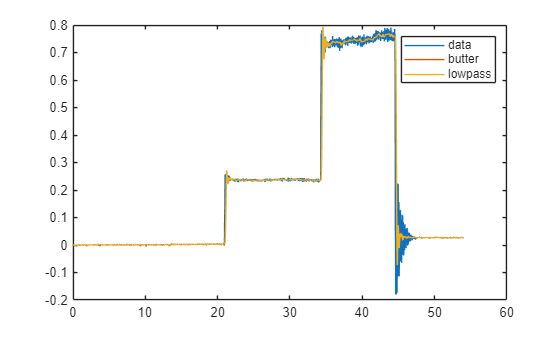

plot(t, t1)
hold on
plot(t, [lines(2,:); lines_lp(2,:)])
hold off
legend("data","butter", "lowpass")

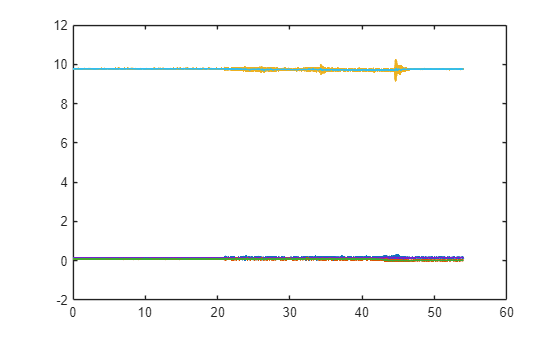


ax = data.out.acc(1:5400, 1);
ay = data.out.acc(1:5400, 2);
az = data.out.acc(1:5400, 3);

gx = data.out.gyro(1:5400, 3);
gy = data.out.gyro(1:5400, 2);
gz = data.out.gyro(1:5400, 1);

t = 0:0.01:53.99;

fs = 85;        % częstotliwość próbkowania [Hz]
fc = 3;         % częstotliwość odcięcia filtru [Hz]

[b, a] = butter(2, fc/(fs/2), 'low');

ax_f_4 = filtfilt(b, a, ax);
ay_f_4 = filtfilt(b, a, ay);
az_f_4 = filtfilt(b, a, az);

plot(t, [ax, ay, az], LineWidth=1.5)
hold on
plot(t, [ax_f_4, ay_f_4, az_f_4], LineWidth=1.5)
hold off

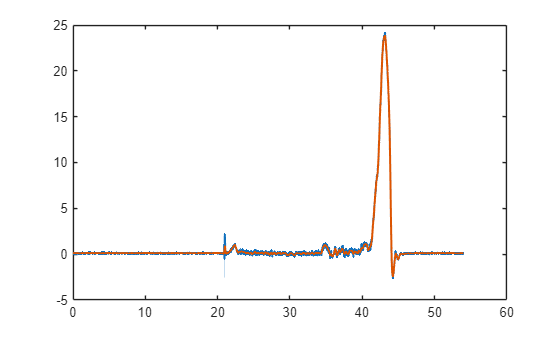


gx_f_4 = filtfilt(b, a, gx);
gy_f_4 = filtfilt(b, a, gy);
gz_f_4 = filtfilt(b, a, gz);


plot(t, gz, LineWidth=1.5)
hold on
plot(t, gz_f_4, LineWidth=1.5)
hold off


avg_x = mean(gx_f_4(:))

avg_x = single
0.0192

avg_y = mean(gy_f_4(:))

avg_y = single
0.1209

avg_z = mean(gz_f_4(:))

avg_z = single
0.8208


% Plot acc
plt = plot(t, [ax_f_4, ay_f_4, az_f_4], LineWidth=1.5)

plt =   3×1 Line array:

  Line
  Line
  Line


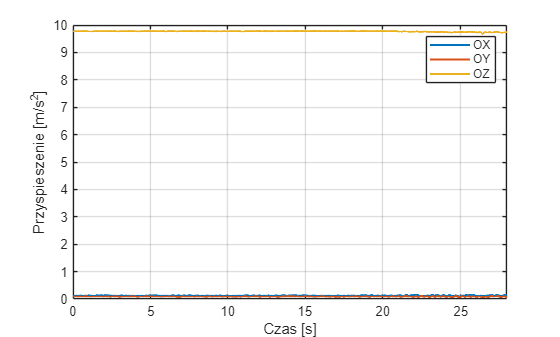

plt(1).Color = [0.0000 0.4470 0.7410];
plt(2).Color = [0.8500 0.3250 0.0980];
plt(3).Color = [0.9290 0.6940 0.1250];

grid on
legend('OX', 'OY', 'OZ')
ylabel("Przyspieszenie [m/s^2]")
xlabel("Czas [s]")
xlim([0, 28])


%plot gyro
plt = plot(t, [gx_f_4, gy_f_4, gz_f_4], LineWidth=1.5)

plt =   3×1 Line array:

  Line
  Line
  Line


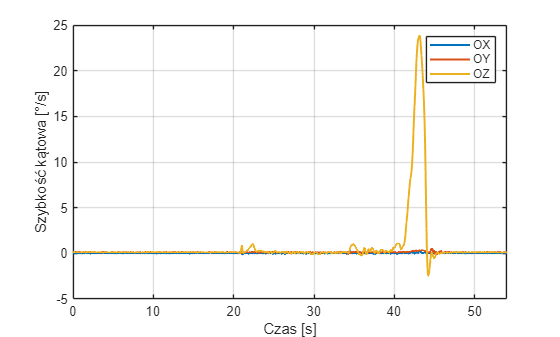

plt(1).Color = [0.0000 0.4470 0.7410];
plt(2).Color = [0.8500 0.3250 0.0980];
plt(3).Color = [0.9290 0.6940 0.1250];

grid on
legend('OX', 'OY', 'OZ')
ylabel("Szybkość kątowa [°/s]")
xlabel("Czas [s]")
xlim([0, 54])


%plot gyro X Y
plt = plot(t, [gx_f_4, gy_f_4], LineWidth=1.5)

plt =   2×1 Line array:

  Line
  Line


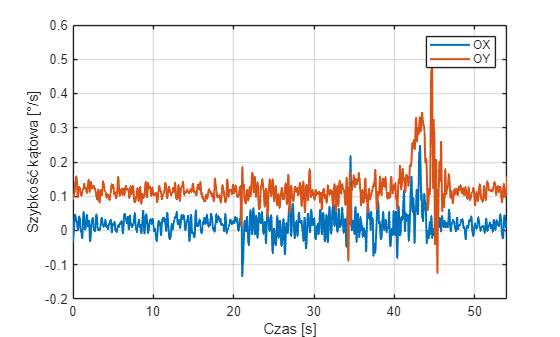

plt(1).Color = [0.0000 0.4470 0.7410];
plt(2).Color = [0.8500 0.3250 0.0980];

grid on
legend('OX', 'OY')
ylabel("Szybkość kątowa [°/s]")
xlabel("Czas [s]")
xlim([0, 54])

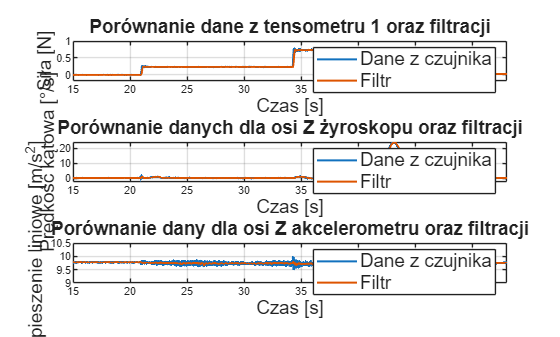

t1 = data.out.tens_cal(1:5400, 1) - data.out.tens_cal(1,1);
t1 = t1 *9.81 / 1000;
az = data.out.acc(1:5400, 3);
gz = data.out.gyro(1:5400, 1);

t = 0:0.01:53.99;

fs = 85;        % częstotliwość próbkowania [Hz]
fc = 3;         % częstotliwość odcięcia filtru [Hz]

[b, a] = butter(2, fc/(fs/2), 'low');

ft1 = filter(b, a, t1);
faz = filter(b, a, az);
fgz = filter(b, a, gz);

figure()
subplot(3, 1, 1);
plot(t, [t1, ft1], LineWidth=1.5);
xlim([0, 54])
ylabel("Siła [N]", 'FontSize', 14)
xlabel("Czas [s]", 'FontSize', 14)
title("Porównanie dane z tensometru 1 oraz filtracji", 'FontSize', 14)
legend("Dane z czujnika", "Filtr", 'FontSize', 14)
grid on
xlim([15 53])

subplot(3, 1, 2);
plot(t, [gz, fgz], LineWidth=1.5);
xlim([0, 54])
xlabel("Czas [s]", 'FontSize', 14)
ylabel("Prędkość kątowa [°/s]", 'FontSize', 14)
title("Porównanie danych dla osi Z żyroskopu oraz filtracji", 'FontSize', 14)
legend("Dane z czujnika", "Filtr", 'FontSize', 14)
grid on
xlim([15 53])

subplot(3, 1, 3);
plot(t, [ az, faz], LineWidth=1.5);
xlim([0, 54])
ylim([9, 10.5])
xlabel("Czas [s]", 'FontSize', 14)
ylabel("Przyspieszenie liniowe [m/s^2]", 'FontSize', 14)
title("Porównanie dany dla osi Z akcelerometru oraz filtracji", 'FontSize', 14)
legend("Dane z czujnika", "Filtr", 'FontSize', 14)
grid on
xlim([15 53])